# **ACM 11 Week 8 In-class Exercise 2 (Spring 2021)**

## **Linear regression for combustion problem**

We provide a data file to you, cdrdata4.m, which contains data from a simuation of a combustion chamber. The simulation takes as its inputs the variables $T_0 ,\phi ,\textrm{and}\;E$, which represent the temperature at which reactants enter the chamber, the mixture fraction of fuel vs oxidizer, and the reaction activation energy, respectively. The output is the maximum temperature reached within the combustion chamber, $T_{\max }$. Each data point in the file took approximately 2 seconds to generate using a finite difference code that solves the convection-diffusion-reaction equation in 2 dimensions. There are ~10000 data points, so generating this data would take 20000 seconds, or about 5.5 hours.

Now that we have this data, we would like to fit a linear model of the following form:

$T_{\max } \approx f\left(T_0 ,\phi ,E\right)=p_1 T_0 +p_2 \phi +p_3 E$.

Having this model lets us rapidly generate many more approximate samples if we want to do Monte Carlo, or rapidly do an optimization using this model to estimate gradients, or any number of useful things.

**(1a)  Linear fit with no intercept: **follow the instructions in the code block below to solve for the parameters $p_1 ,p_2 ,p_3$ via linear regression, and calculate the relative residual and R^2 values of your linear fit.

Kyle McGraw and Dallas Taylor

% (i) Use the LOAD('cdrdata4.mat') to load the data set. It will load four
% variables into your workspace, T0, phi, E, and maxT. Each one will be a 10033x1
% vector
load('cdrdata4.mat');

% (ii) We want to use the inlet temperature, T0, fuel mixture fraction phi,
% and activation energy E to predict the combustor's max temperature maxT.
% set up the data matrix X so that each column is one of the input
% variables and set up the output data y so that it is the output variable.
X = [T0,phi,E];
y = maxT;

% (iii) Use the backslash operator "\" to solve the least square problem
% for the parameters of our linear model.
p = [T0,phi,E]\maxT;

% (iv) Use your computed parameters to calculate the regression prediction
% following the model equation above. Your answer should be a vector the
% same shape as y.
regpred = p(1).*T0 + p(2).*phi + p(3).*E;

% (v) Compute the relative error, norm(X-y)/norm(y), and the R^2 value of
% your regression fit:
rel_err = norm(regpred-y)/norm(y)

rel_err = 0.0198

R2 = 1 - (norm(regpred-y)^2) / (norm(y - mean(y))^2)

R2 = 0.9894

The code block below plots the output of the regression model along with the exact values if you set visualize = 1 or visualize = true. Only plot once you've completed the code above because otherwise some variables won't be defined.

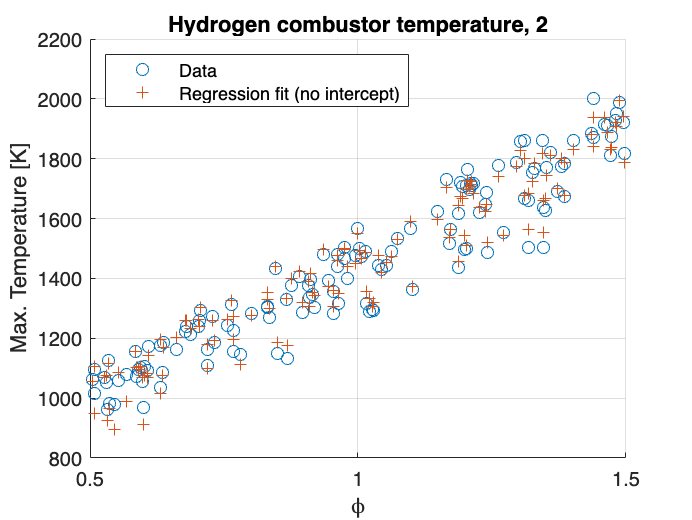

% plot results
visualize = true;
if visualize
    figure(1); clf
    scatter(T0,y); hold on
    grid on
    plot(T0,regpred,'+')
    legend('Data','Regression fit (no intercept)','Location','NorthWest')
    xlabel('T_0 [K]')
    ylabel('Max. Temperature [K]')
    title('Hydrogen combustor temperature, 1')
    
    figure(2); clf
    scatter(phi,y); hold on
    grid on
    plot(phi,regpred,'+')
    legend('Data','Regression fit (no intercept)','Location','NorthWest')
    xlabel('\phi')
    ylabel('Max. Temperature [K]')
    title('Hydrogen combustor temperature, 2')
    
%  Commented out the below in order to see other figures
%     figure(3); clf
%     scatter(E,y); hold on
%     grid on
%     plot(E,regpred,'+')
%     legend('Data','Regression fit (no intercept)','Location','NorthEast')
%     xlabel('E')
%     ylabel('Max. Temperature [K]')
%     title('Hydrogen combustor temperature, 3')
end

**(1b) Perturbation experiment:** calculate the relative error and R^2 values if we used $1\ldotp 01p\;\textrm{or}\;0\ldotp 99p$ instead of $p$. These should be worse than using $p$.

% (vi) calculate the perturbed regression prediction, relative error, and
% R^2 value
perturb_pred = 0.99*p(1).*T0 + 0.99*p(2).*phi + 0.99*p(3).*E;
rel_err_perturb = norm(perturb_pred-y)/norm(y)

rel_err_perturb = 0.0222

R2_perturb = 1 - norm(perturb_pred-y)^2 / norm(y - mean(y))^2

R2_perturb = 0.9867

What does this demonstrate about the values of $p$ found via linear regression?

This demonstrates that the values of p found via linear regression are sensitive to small changes in p, and that we are minimizing the error.

**(2) Feature selection: **Look at the scatter plots of the data and your regression prediction. Which input variable appears to be most strongly correlated with the maximum temperature? Let's call that variable $z$. In the code block below, fit a line-of-best fit to that variable, i.e., a model of the form

$T_{\max } \approx f\left(z\right)=p_0 +p_1 z$.

Calculate the R^2 and relative error of your linear model in one variable. You should be able to copy-and-paste most of your code from before, but updating your regression matrix to have one column of just 1's (use `ones(N,1)` to an Nx1 vector of 1's) and one column of all the $z$-values.

z = phi;
p = [ones(10033,1), z]\maxT;
regpred = p(1) + p(2).*z;
rel_err = norm(regpred-y)/norm(y)

rel_err = 0.0586

R2 = 1 - (norm(regpred-y)^2) / (norm(y - mean(y))^2)

R2 = 0.9076

In application, fitting a model with fewer inputs may allow the regression to issue predictions faster. However, this comes with a cost - what is this cost? (Compare the R^2 values and relative errors of the two models you have fitted).

The cost is that we have an increase in relative error and a decrease in R2 error (although this corresponds to higher error we think) and thus our predictions become less accurate as we use fewer inputs.